load("total_biomass_M0.txt")
%load("total_biomass_M4.txt")
%load("total_biomass_M8_39.txt")
load("total_biomass_M16.txt")
%load("total_biomass_Noise0_000001.txt")
%load("total_biomass_M32.txt")

f=plot(0.05*total_biomass_M0(1:5000,1)/24,total_biomass_M0(1:5000,2),LineWidth=2)

f =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0021 0.0042 0.0063 0.0083 0.0104 0.0125 0.0146 0.0167 0.0187 0.0208 0.0229 0.0250 0.0271 0.0292 0.0312 0.0333 0.0354 0.0375 0.0396 0.0417 0.0438 0.0458 0.0479 0.0500 0.0521 0.0542 0.0563 0.0583 0.0604 0.0625 0.0646 0.0667 … ]
              YData: [1.2104e-04 1.3056e-04 1.4061e-04 1.4975e-04 1.5685e-04 1.6191e-04 1.6605e-04 1.6965e-04 1.7304e-04 1.7608e-04 1.7914e-04 1.8208e-04 1.8496e-04 1.8771e-04 1.9029e-04 1.9285e-04 1.9536e-04 1.9777e-04 2.0022e-04 2.0260e-04 … ]

  Show all properties


hold on
%f=plot(0.05*total_biomass_M4(1:5000,1)/24,total_biomass_M4(1:5000,2),LineWidth=2)
%hold on
%f=plot(0.05*total_biomass_Noise0_000001(1:4001,1)/24,total_biomass_Noise0_000001(1:4001,2),LineWidth=1.5)
%hold on
%f=plot(0.05*total_biomass_M8_39(1:5000,1)/24,total_biomass_M8_39(1:5000,2),LineWidth=1.5)
%hold on
f=plot(0.05*total_biomass_M16(1:5000,1)/24,total_biomass_M16(1:5000,2),LineWidth=1.5)

f =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0021 0.0042 0.0063 0.0083 0.0104 0.0125 0.0146 0.0167 0.0187 0.0208 0.0229 0.0250 0.0271 0.0292 0.0312 0.0333 0.0354 0.0375 0.0396 0.0417 0.0438 0.0458 0.0479 0.0500 0.0521 0.0542 0.0563 0.0583 0.0604 0.0625 0.0646 0.0667 … ]
              YData: [1.2104e-04 1.2970e-04 1.3902e-04 1.4744e-04 1.5377e-04 1.5771e-04 1.6103e-04 1.6404e-04 1.6686e-04 1.6934e-04 1.7179e-04 1.7409e-04 1.7633e-04 1.7848e-04 1.8055e-04 1.8264e-04 1.8450e-04 1.8631e-04 1.8811e-04 1.8982e-04 … ]

  Show all properties

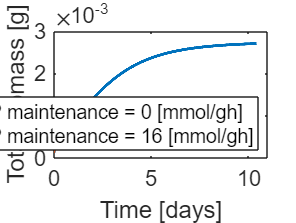

ax =   Axes with properties:

             XLim: [0 11]
             YLim: [0 0.0030]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1144 0.7750 0.8106]
            Units: 'normalized'

  Show all properties


hold on
%f=plot(0.05*total_biomass_M32(1:5000,1)/24,total_biomass_M32(1:5000,2),LineWidth=1.5)
%hold on

xlim([0,11])
ylim([0,3e-3])
xlabel('Time [days]')
ylabel('Total biomass [g]')
legend('ATP maintenance = 0 [mmol/gh]','ATP maintenance = 16 [mmol/gh]','Location','southeast')
ax=gca;
ax.FontSize=13

exportgraphics(gcf,'total_biomass.png','Resolution', 300)